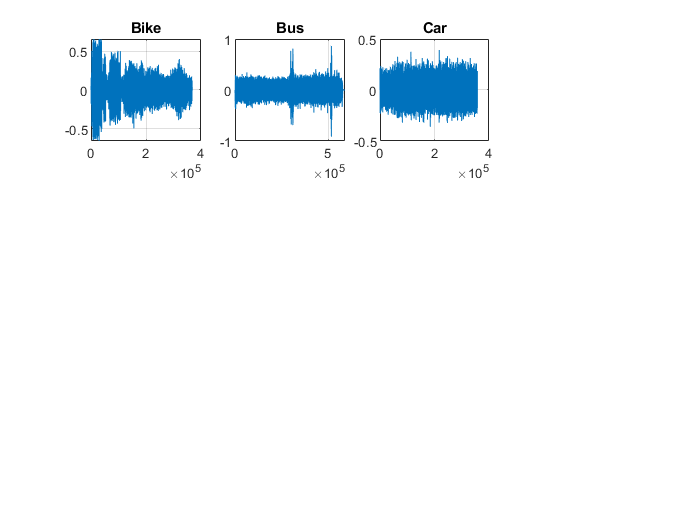

clear all
clc
warning("off")

%Import the dataset of each class
datafolder = "D:\VIT\VIT STUDY MATERIAL\SEM5\DSP\DSP project\Vehicles";

%Labels Class/Categories
Data_Class = categorical(["Bike","Car","Bus"]);

figure()
currentfolder = pwd;
cd(datafolder);
listdir=dir;  
for i=3:1:length(listdir)
    cd(listdir(i).name)
    inside=dir;
    subplot(3,4,i-2);
    [y,fs]=audioread(inside(4).name);
    plot(y(:,:)); 
    soundsc(y(:,:),fs);
    grid on;
    title(listdir(i).name)
    drawnow;
    pause(2)
    cd(strcat(datafolder));
end

cd(currentfolder);
clear all

datafolder = "D:\VIT\VIT STUDY MATERIAL\SEM5\DSP\DSP project\Vehicles";

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames')

ads =   audioDatastore with properties:

                       Files: {
                              'D:\VIT\VIT STUDY MATERIAL\SEM5\DSP\DSP project\Vehicles\Bike\Bike1.wav';
                              ' ...\VIT\VIT STUDY MATERIAL\SEM5\DSP\DSP project\Vehicles\Bike\Bike10.wav';
                              ' ...\VIT\VIT STUDY MATERIAL\SEM5\DSP\DSP project\Vehicles\Bike\Bike11.wav'
                               ... and 46 more
                              }
                      Labels: [Bike; Bike; Bike ... and 46 more categorical]
    AlternateFileSystemRoots: {}
              OutputDataType: 'double'


G1=countEachLabel(ads)

G1 = 3×2 table
    Label    Count
    _____    _____

    Bike      15  
    Bus       15  
    Car       19  


mono=1;
stereo=1;
for i=1:1:length(ads.Files)
    y=audioread(ads.Files{i});
    if size(y,2) == 1
        mono=mono+1;
    else
        stereo=stereo+1;
    end
end

Percentage_Mono = mono/(mono+stereo)*100

Percentage_Mono = 98.0392

Percentage_Stereo = stereo/(mono+stereo)*100

Percentage_Stereo = 1.9608

for i=1:1:length(ads.Files)
    [y,fs(i)]=audioread(ads.Files{i});
end
Overall =table(categories(categorical(fs)),countcats(categorical(fs))');
Overall.Properties.VariableNames{1}='Frequency';
Overall.Properties.VariableNames{2}='Occurences'

Overall = 1×2 table
    Frequency    Occurences
    _________    __________

     '44100'         49    


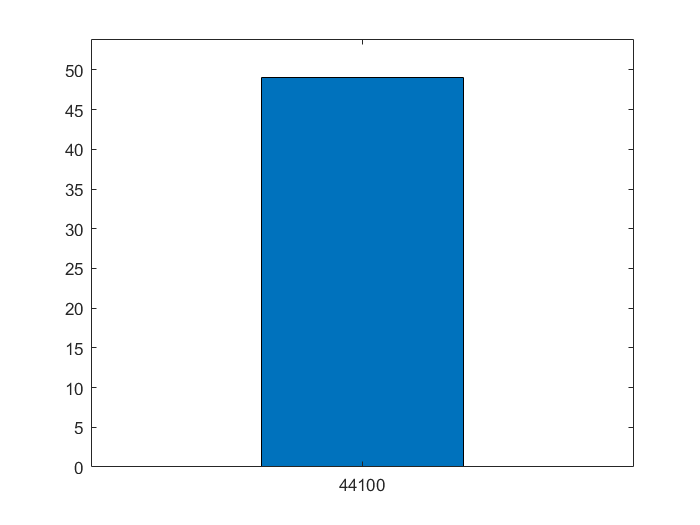

%Plot the histogram distribution and explain
figure();
hist(categorical(fs))

mode(fs)

ans = 44100

for i=1:1:length(ads.Files)
    info = audioinfo(ads.Files{i});
    if strcmp(info.CompressionMethod,'Uncompressed')
         Bits(i)=info.BitsPerSample;
    else
        Bits(i)=0;
    end
end

%Plot the histogram distribution and explain
Overall2 =table(categories(categorical(Bits)),countcats(categorical(Bits))');
Overall2.Properties.VariableNames{1}='Bits';
Overall2.Properties.VariableNames{2}='Occurences'

Overall2 = 1×2 table
    Bits    Occurences
    ____    __________

    '16'        49    


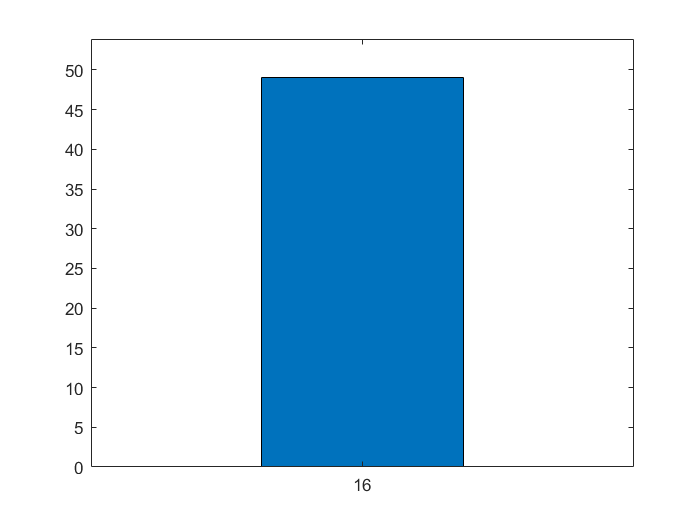

figure();
hist(categorical(Bits))

mode(Bits)

ans = 16

for i=1:1:length(ads.Files)
    y =audioread(ads.Files{i});
    if size(y,2) == 1
        result = y;
    else
        result = (y(:,1)+y(:,2))/2;
    end
    audiowrite(ads.Files{i},result,44100,'BitsPerSample',16);
    clear y Fs result
end

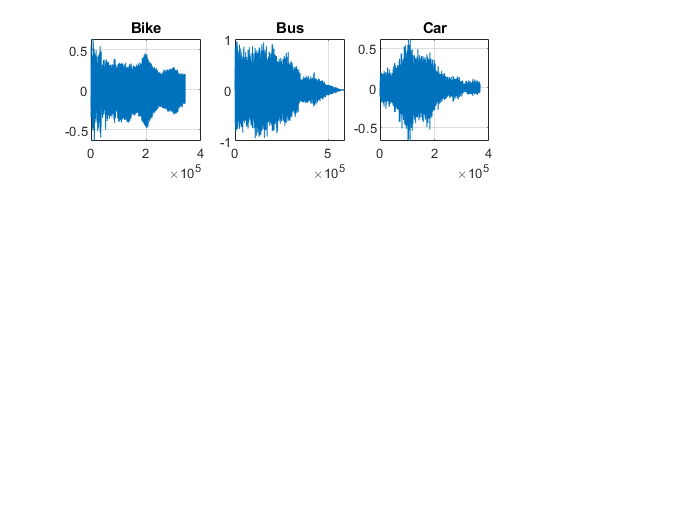

figure()
currentfolder = pwd;
cd(datafolder);
listdir=dir;  
for i=3:1:length(listdir)
    cd(listdir(i).name)
    inside=dir;
    subplot(3,4,i-2);
    [y,fs]=audioread(inside(randi([3,length(inside)])).name);
    plot(y(:,:)); 
    soundsc(y(:,:),fs);
    grid on;
    title(listdir(i).name)
    drawnow;
    pause(2)
    cd(strcat(datafolder));
end

cd(currentfolder);

ads = audioDatastore(datafolder, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

for i=1:1:length(ads.Files)
    y =audioread(ads.Files{i});
    signal{i}=y;
    labels(i)= ads.Labels(i);
end

tablefordiagnostic = table(signal',labels');
tablefordiagnostic.Properties.VariableNames{1} = 'Signal';
tablefordiagnostic.Properties.VariableNames{2} = 'Label';
head(tablefordiagnostic)

ans = 8×2 table
         Signal          Label
    _________________    _____

    [366854×1 double]    Bike 
    [368735×1 double]    Bike 
    [366854×1 double]    Bike 
    [368735×1 double]    Bike 
    [372498×1 double]    Bike 
    [356505×1 double]    Bike 
    [363090×1 double]    Bike 
    [368735×1 double]    Bike 


diagnosticFeatureDesigner

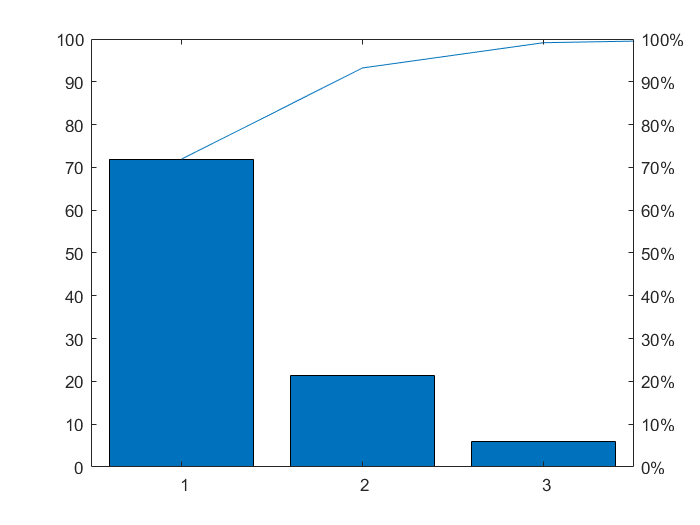

[coeff,score,latent,tsquared,explained] = pca(FeatureTable1{:,1:13});
figure()
pareto(explained)

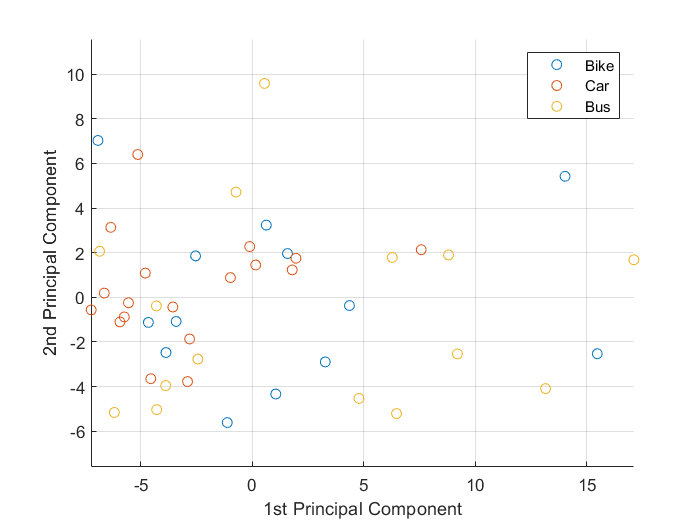

Data_Class = categorical(["Bike","Car","Bus"]);
figure()
for i =1:1:length(categories(FeatureTable1.Label))
scatter(score(FeatureTable1{:,14}==Data_Class(i),1),score(FeatureTable1{:,14}==Data_Class(i),2))
hold on
axis equal
end
legend('Bike', 'Car', 'Bus')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
grid on

head(FeatureTable1)

ans = 8×14 table
    Signal_stats_Col1_PeakValue    Signal_ps_spec_Col1_PeakFreq1    Signal_stats_Col1_Mean    Signal_stats_Col1_Skewness    Signal_stats_Col1_ShapeFactor    Signal_ps_spec_Col1_BandPower    Signal_stats_Col1_RMS    Signal_stats_Col1_Std    Signal_stats_Col1_Kurtosis    Signal_stats_Col1_ClearanceFactor    Signal_stats_Col1_CrestFactor    Signal_stats_Col1_ImpulseFactor    Signal_stats_Col1_SINAD    Label
    ___________________________    _____________________________    ______________________    __________________________    _____________________________    _____________________________    _____________________    

FeatureTable1{:,1:13} = normalize(FeatureTable1{:,1:13},'range');
head((FeatureTable1))

ans = 8×14 table
    Signal_stats_Col1_PeakValue    Signal_ps_spec_Col1_PeakFreq1    Signal_stats_Col1_Mean    Signal_stats_Col1_Skewness    Signal_stats_Col1_ShapeFactor    Signal_ps_spec_Col1_BandPower    Signal_stats_Col1_RMS    Signal_stats_Col1_Std    Signal_stats_Col1_Kurtosis    Signal_stats_Col1_ClearanceFactor    Signal_stats_Col1_CrestFactor    Signal_stats_Col1_ImpulseFactor    Signal_stats_Col1_SINAD    Label
    ___________________________    _____________________________    ______________________    __________________________    _____________________________    _____________________________    _____________________    

rng(1)
cvp = cvpartition(FeatureTable1.Label,'HoldOut',0.7)

cvp = Hold-out cross validation partition
   NumObservations: 49
       NumTestSets: 1
         TrainSize: 15
          TestSize: 34

dataTrain_Validation = FeatureTable1(cvp.training,:);
dataTest = FeatureTable1(cvp.test,:);

dataTrain_Validation{:,15}=string(dataTrain_Validation{:,14});
dataTrain_Validation(:,14)=[];
dataTrain_Validation.Properties.VariableNames{14} = 'Label';

dataTest{:,15}=string(dataTest{:,14});
dataTest(:,14)=[];
dataTest.Properties.VariableNames{14} = 'Label';

classificationLearner

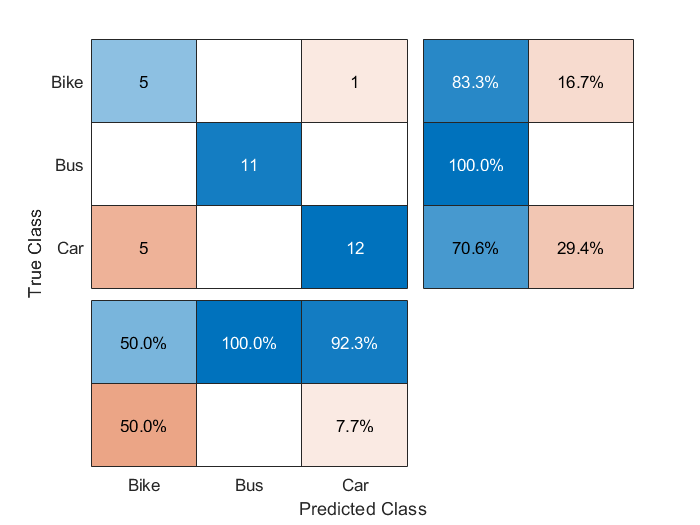

[predictionoutcome,scores]=trainedModel.predictFcn(dataTest);
fig = figure;
cm = confusionchart(string(predictionoutcome),dataTest.Label,'RowSummary','row-normalized','ColumnSummary','column-normalized');

accuracy=sum(string(predictionoutcome)==dataTest.Label)/length(dataTest.Label)

accuracy = 0.8235

saveCompactModel(trainedModel.ClassificationEnsemble,'subspacediscriminant');

cd(datafolder)

X = dataTest(15,1:13);
modl = loadCompactModel('D:\VIT\VIT STUDY MATERIAL\SEM5\DSP\DSP project\subspacediscriminant');
lab = predict(modl,X)

lab = 1×1 cell array
    {'Bus'}
